## Import Data

## Set up the Import Options and import the data

folder = "C:\Users\Donovan\Documents\MATLAB\EspectrosPo_Gly";
grattingID = "15"+"-"+"11";
curves = readmatrix(folder+"\TFBG"+grattingID+"_Po.csv")

curves = 	1.0e+03 *

         0    0.0010    0.0013    0.0013    0.0013    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0015    0.0015
    1.4700    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008
    1.4700    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0

cutoffPoints = readmatrix(folder+"\Metodo2\GlicerinaM2_FibraV2_TFBG"+grattingID+"_RI.csv")

cutoffPoints = 	1.0e+03 *

       NaN         0
    0.0013    1.5300
    0.0013    1.5285
    0.0013    1.5297
    0.0014    1.5291
    0.0014    1.5300
    0.0014    1.5305
    0.0014    1.5315
    0.0014    1.5326
    0.0014    1.5335


## Plot

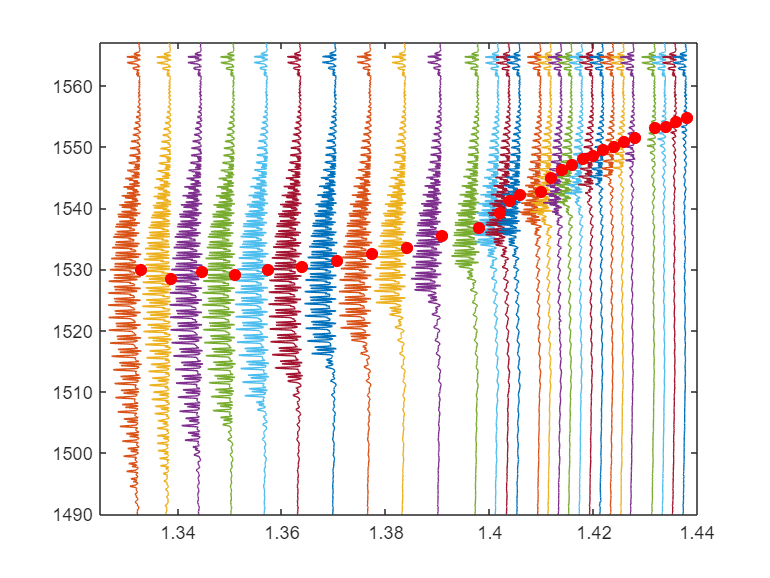

% To plot lambda from a starting point
lambdaInit = 1490;
initPos = find(curves(1:end,1) == lambdaInit);
lambda = curves(initPos:end ,1 );
nCols = length(curves(1,1:end-7));

% Save cutoffs as a curve
cutoffCurve = zeros([nCols-2,2]);

% If want a vector with refractive index
refractiveIndex = curves(1, 2:end);

escaladoIntesity = 100;
% for to plot all curves
for n = 2:nCols
    intensity = curves(initPos:end, n);
    delta = refractiveIndex(n-1);
    intensity = (intensity./escaladoIntesity) + (delta-max(intensity)./escaladoIntesity);
    plot(intensity,lambda)
    hold on
    % To save the values on cutoff curve
    if (n>2)
       %lambdaCutoffPos = find(lambda == cutoffPoints(n-1, 2));
       cutoffCurve(n-2,2) = cutoffPoints(n-1,2) ;
       abscissaCutoff = (delta);
       cutoffCurve(n-2,1) = abscissaCutoff;
    end

end
plot(cutoffCurve(1:end,1),cutoffCurve(1:end,2),".r","MarkerSize",20)
% legends = curves(1,2:end  
% legends = arrayfun(@num2str,legends,'un',0);
% legend(legends)
% 
% legend('Position',[0.9352,-0.031111,0.14643,1.0048])

%xlim([1-0.008 cutoffCurve(end,1)+0.002])
xlim([cutoffCurve(1,1)-0.008 cutoffCurve(end,1)+0.002])
ylim([lambdaInit 1567])
%legend(num2str(refractiveIndex))
hold off

clear lambda lambdaCutoffPos initPos f1 abscissaCutoff n nCols intensity initPos delta cutoffCurve lambdaInit
clf

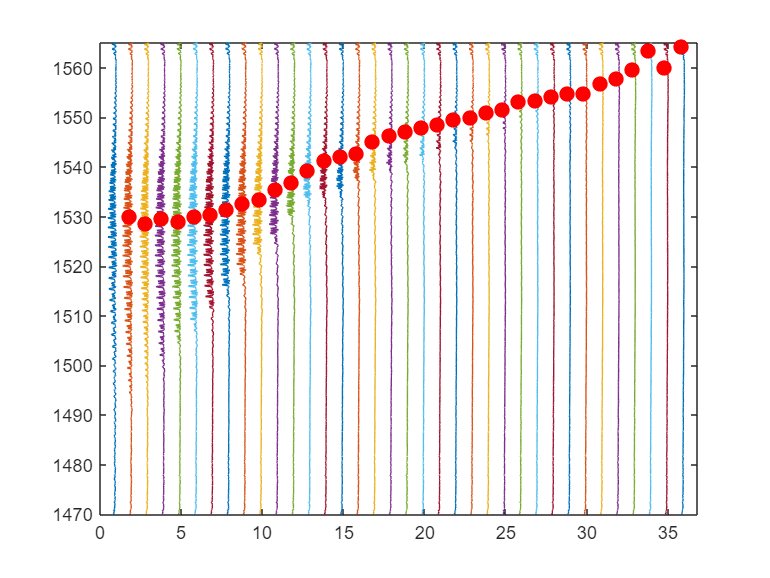

% To plot lambda from a starting point
lambdaInit = 1470;
initPos = find(curves(1:end,1) == lambdaInit);
lambda = curves(initPos:end ,1 );
nCols = length(curves(1,1:end));

% Save cutoffs as a curve
cutoffCurve = zeros([nCols-2,2]);

% If want a vector with refractive index
refractiveIndex = curves(1, 2:end);

% for to plot all curves
for n = 2:nCols
    intensity = curves(initPos:end, n);
    delta = 1;
    intensity = intensity + (n-2)*delta;
    plot(intensity,lambda)
    hold on
    % To save the values on cutoff curve
    if (n>2)
       %lambdaCutoffPos = find(lambda == cutoffPoints(n-1, 2));
       cutoffCurve(n-2,2) = cutoffPoints(n-1,2) ;
       abscissaCutoff = ((n-1)*delta)-0.2;
       cutoffCurve(n-2,1) = abscissaCutoff;
    end

end
plot(cutoffCurve(1:end,1),cutoffCurve(1:end,2),".r","MarkerSize",25)
% legends = curves(1,2:end  
% legends = arrayfun(@num2str,legends,'un',0);
% legend(legends)
% 
% legend('Position',[0.9352,-0.031111,0.14643,1.0048])
xlim([0 cutoffCurve(end,1)+1])
ylim([lambdaInit 1565])
%legend(num2str(refractiveIndex))
hold off

clear lambda lambdaCutoffPos initPos f1 abscissaCutoff n nCols intensity initPos delta cutoffCurve lambdaInit
clf